clear; clc;

N = 400; 

f = waitbar(0, "Loading Data ...");
for mem = 40:60
    waitbar((mem-39)/21, f, sprintf("Loading Data ..."));
    varName = sprintf('ttfs%d', mem);
    filePath = sprintf('Data/Scaled50/N%d/Apr_23_2025_06_50_15/Memory%dRecalls.mat', N, mem);
    data = load(filePath);
    assignin('base', varName, data.TTFS);
end
close(f)

  Name            Size                    Bytes  Class               Attributes

  N               1x1                         8  double                        
  data            1x1                 320000148  struct                        
  f               1x1                         8  matlab.ui.Figure              
  filePath        1x59                      118  char                          
  mem             1x1                         8  double                        
  ttfs40        400x100000            320000000  double                        
  ttfs41        400x100000            320000000  double                        
  ttfs42        400x100000            320000000  double                        
  ttfs43        400x100000            320000000  double                        
  ttfs44        400x100000            320000000  double                        
  ttfs45        400x100000            320000000  double                        
  ttfs46        400x100000            3

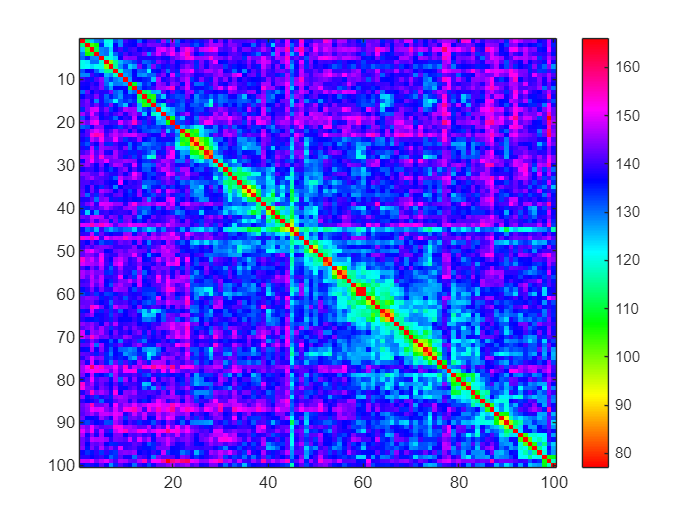

mat = squareform(pdist(ttfs45(:, 1000:1000:end)', 'euclidean'));

% Replace diagonal values with NaN
mat(1:size(mat,1)+1:end) = nan;


% Plot
figure;
imagesc(mat);
colormap('hsv');
cb = colorbar();

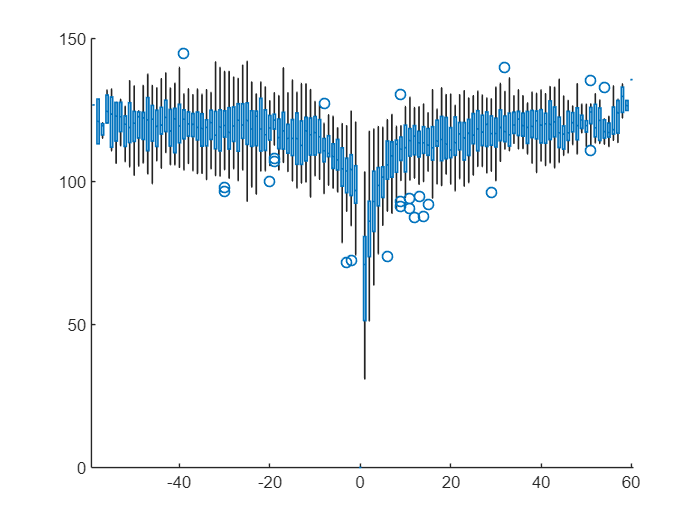

mem = 50;


groups = [];
x = [];

for mem = 40:60
    eval(sprintf("mat = squareform(pdist(ttfs%d(:, 1000:1000:end)', 'euclidean'));", mem))
    dd = mat(mem, :);
    groups = [groups, (1:100)-mem];
    x = [x, dd];
end

figure; hold on;
boxchart(groups, x)